# Setup

clc
clear
warning('off')

%Input signals

%Position Input
N_temp = 534; %TODO: Increase time to match Land (issues with stitching chirp)
delta_t = 0.01;
t = 0:delta_t:2*N_temp*delta_t;
NT = 2*N_temp;
t1 = 0:delta_t:N_temp*delta_t;
I_p(1:N_temp+1) = 1-chirp(t1,0.5,N_temp*delta_t,1);
I_p(N_temp+1:2*N_temp+1) = 1-chirp(t1,1,N_temp*delta_t,3);

%Velocity Input
I_v = diff(I_p)/delta_t;

%Time Alignment
I_p = I_p(1:NT);
t = t(1:NT);

%Concatenate Time Series
P_in = [t;I_p]';
V_in = [t;I_v]';

# "G" Model

%Model "g"
%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'g';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
VSA = 0.05;
VSM = 0.8;

%Delay and zero-order hold time
delay = 0.1;

%Simulate
out = sim('g.slx');

%Outputs
g_pout = P_out;
g_vout = V_out;

%Position Error
g_error = abs(g_pout-P_in(:,2));

# Smooth TF model

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (position)
PD = tf([K_D K_P],[1 0]);

%Pade Approximation
s = tf('s');
sys = exp(-d*s);
delayPade = pade(sys,2);

%G(s)
G = PD*delayPade%sys;

G =
 
  0.8 s^3 - 48 s^2 + 960 s
  ------------------------
   s^3 + 60 s^2 + 1200 s
 
Continuous-time transfer function.




%Feedback
TF_sm = G/(1+G)

TF_sm =
 
                                           
           0.8 s^6 - 960 s^4 + 1.152e06 s^2
                                           
  ---------------------------------------------------
                                                     
  1.8 s^6 + 120 s^5 + 5040 s^4 + 144000 s^3          
                                                     
                                       + 2.592e06 s^2
                                                     
 
Continuous-time transfer function.




%Simulate
out = sim('HybridModel.slx');

%Outputs
stf_pout = out.P_out;

%Position Error
stf_error = abs(stf_pout-P_in(:,2));

# Plot Original Simulink vs. Hybrid with Smooth Continuous TF

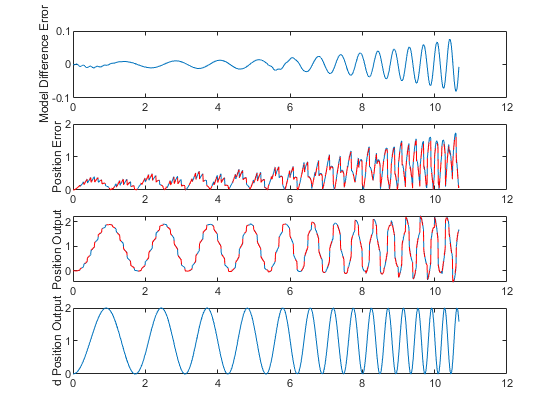

figure
subplot(4,1,1)
plot(t,g_pout-stf_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stf_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stf_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Smooth TF model: Discrete

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t)

tfz =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



z_delay = tfz^(-10);
G_d = z_delay*PD_d

G_d =
 
  0.8
  ----
  z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%TF for PD feedback
TF_sm = G_d/(1+G_d)

TF_sm =
 
     0.8 z^10
  ---------------
  z^20 + 0.8 z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%Simulate
out = sim('HybridModel.slx');

%Outputs
stfd_pout = out.P_out;

%Position Error
stfd_error = abs(stfd_pout-P_in(:,2));

# Plot Original Simulink vs. Hybrid with Smooth Discrete TF

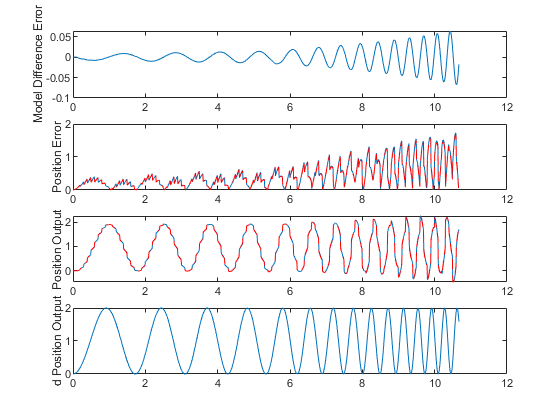

figure
subplot(4,1,1)
plot(t,g_pout-stfd_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stfd_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfd_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Smooth TF model: Discrete + Discretized Saccades

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel1';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t)

tfz =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



z_delay = tfz^(-10);
G_d = z_delay*PD_d

G_d =
 
  0.8
  ----
  z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%TF for PD feedback
TF_sm = G_d/(1+G_d)

TF_sm =
 
     0.8 z^10
  ---------------
  z^20 + 0.8 z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%Simulate
out = sim('HybridModel1.slx');

%Outputs
stfds_pout = out.P_out;

%Position Error
stfds_error = abs(stfds_pout-P_in(:,2));

# Plot Original Simulink vs. Hybrid1

figure
subplot(4,1,1)
plot(t,g_pout-stfds_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stfds_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfds_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Smooth TF model: Discrete + Discretized, combined Saccade paths

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel2';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t)

tfz =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



z_delay = tfz^(-10);
G_d = z_delay*PD_d

G_d =
 
  0.8
  ----
  z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%TF for PD feedback
TF_sm = G_d/(1+G_d)

TF_sm =
 
     0.8 z^10
  ---------------
  z^20 + 0.8 z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.




%Discrete Saccades
tfzd = tf('z',delay)

tfzd =
 
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



tf_sv = VSA*2*(tfzd-1)/(delay*tfzd*(tfzd+1))

tf_sv =
 
    0.1 z - 0.1
  ---------------
  0.1 z^2 + 0.1 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



tf_sp = 1/tfzd

tf_sp =
 
  1
  -
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



TF_sac = 0.5*(tf_sv+tf_sp)

TF_sac =
 
       0.1 z^2
  -----------------
  0.1 z^3 + 0.1 z^2
 
Sample time: 0.1 seconds
Discrete-time transfer function.




%Simulate
out = sim('HybridModel2.slx');

%Outputs
stfdss_pout = out.P_out;

%Position Error
stfdss_error = abs(stfdss_pout-P_in(:,2));

# Plot Original Simulink vs. Hybrid2

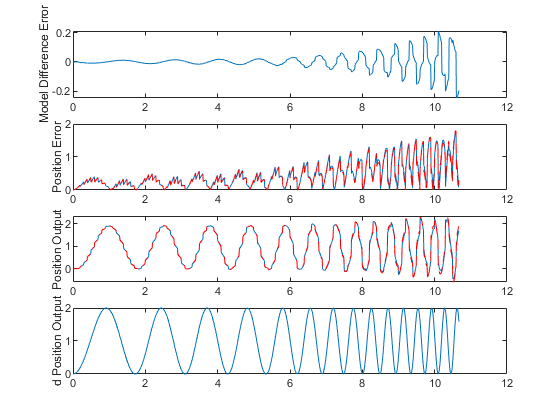

figure
subplot(4,1,1)
plot(t,g_pout-stfdss_pout)
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stfdss_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfdss_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')